clear

x = Grid1DUnifPrimal([0,1],101);
grid = GridSpace1D(x);
p = GridFunction(grid,Label="Pressure",Units="Pa")

p =   GridFunction with properties:

      grid: [1×1 GridSpace1D]
    values: [101×1 double]
     label: "Pressure"
     units: "Pa"
         N: 101
       dim: 1


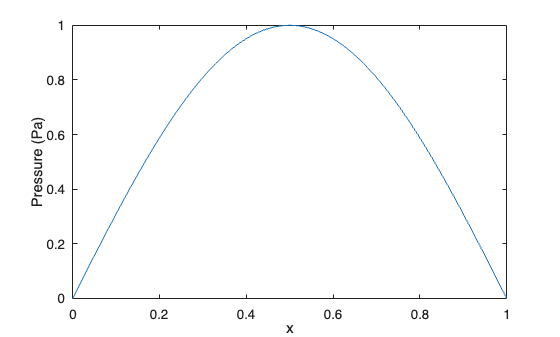

p.setValues(sin(pi*x.pts));
p.plot;

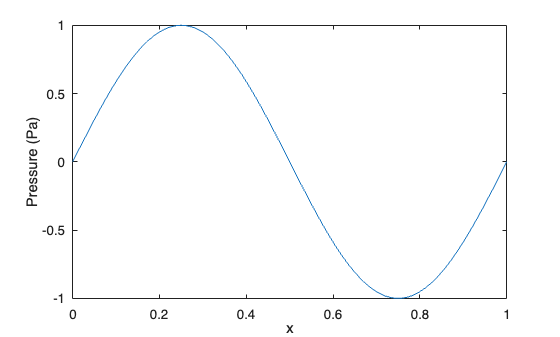


p.setValues(@(x) sin(2*pi*x));
p.plot;

x_coarse = Grid1DUnifPrimal([0,1],11);
grid_coarse = GridSpace1D(x_coarse);
u_coarse = GridFunction(grid_coarse,Label="Pressure",Units="Pa")

u_coarse =   GridFunction with properties:

      grid: [1×1 GridSpace1D]
    values: [11×1 double]
     label: "Pressure"
     units: "Pa"
         N: 11
       dim: 1


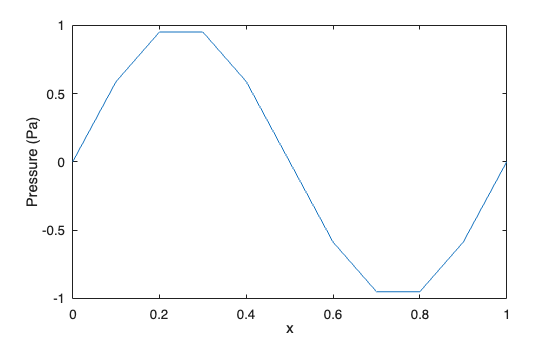

u_coarse.interpolateFrom(p);
u_coarse.plot;

x = Grid1DUnifPrimal([0,1],101);
y = Grid1DUnifPrimal([0,2],81);
grid = GridSpace2D(x,y);
v = GridFunction(grid,Label="Velocity",Units="m/s")

v =   GridFunction with properties:

      grid: [1×1 GridSpace2D]
    values: [101×81 double]
     label: "Velocity"
     units: "m/s"
         N: [101 81]
       dim: 2


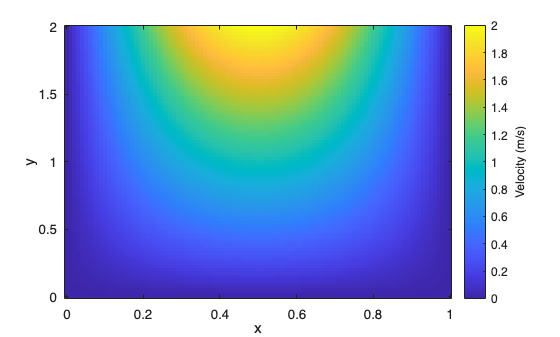


v.setValues(@(x,y) sin(pi*x).*y);

figure
v.plot;
ax = gca;
ax.YDir = "normal";


x_coarse = Grid1DUnifPrimal([0,1],7);
y_coarse = Grid1DUnifPrimal([0,2],11);
grid_coarse = GridSpace2D(x_coarse,y_coarse);
v_coarse = GridFunction(grid_coarse)

v_coarse =   GridFunction with properties:

      grid: [1×1 GridSpace2D]
    values: [7×11 double]
     label: "Value"
     units: ""
         N: [7 11]
       dim: 2


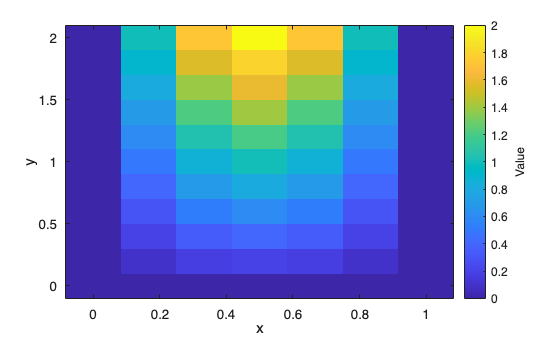

figure
v_coarse.interpolateFrom(v);
v_coarse.plot;
axc = gca;
axc.YDir = "normal";